**Finite Difference Methods for Elliptic PDEs**

Poisson Equations


$$-\Delta u = f$$


in FD scheme( Replacing the dervatives by finite differences )


$$-\left( \frac{u_{i-\text{1,}j}-2u_{i,j}+u_{i+\text{1,}j}}{\Delta x^2}+\frac{u_{i,j-1}-2u_{i,j}+u_{i,j+1}}{\Delta y^2} \right) =f_{i,j}
$$


in tensor product form( with quadrilateral mesh )

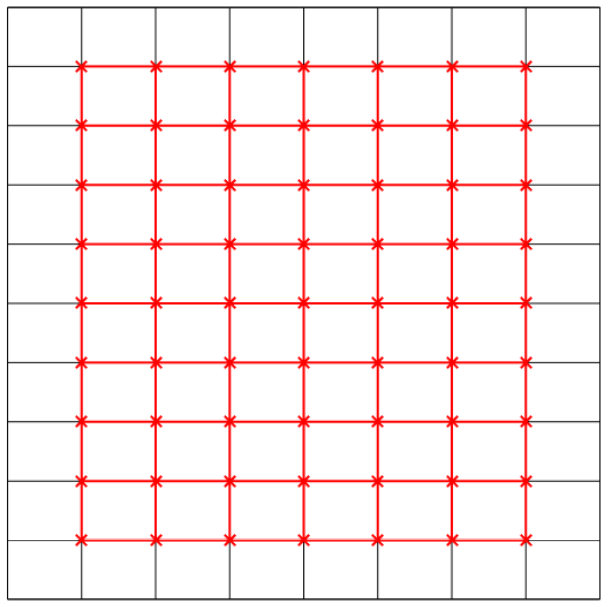


$$\left( A_1\otimes I_N+I_M\otimes A_2 \right) \mathbf{u}=\mathbf{f}$$


where


$$A_{1}=\frac{1}{\Delta x^2}\left[\begin{array}{cccc}{2} & {-1} & {} & {} \\ {-1} & {2} & {-1} & {} \\ {} & {\ddots} & {\ddots} & {\ddots} \\ {} & {} & {-1} & {2}\end{array}\right]_{M \times M}A_{2}=\frac{1}{\Delta y^2}\left[\begin{array}{cccc}{2} & {-1} & {} & {} \\ {-1} & {2} & {-1} & {} \\ {} & {\ddots} & {\ddots} & {\ddots} \\ {} & {} & {} & {-1} & {2}\end{array}\right]_{N \times N}$$



$$\mathbf{u}=\left[u_{11}, u_{12}, \ldots, u_{1 N}, u_{21} \ldots, u_{2 N}, \ldots, u_{M 1}, \ldots u_{M N}\right]^\text{T}$$



$$\mathbf{f}=\left[f_{11}, f_{12}, \ldots, f_{1 N}, f_{21} \ldots, f_{2 N}, \ldots, f_{M 1}, \ldots f_{M N}\right]^\text{T}$$


error_Max_norm


$$\left\|\mathbf{u}-\mathbf{au}\right\|_{\infty}$$


error_L2_norm


$$\sqrt{\left( \Delta x \right) \left( \Delta y \right) \left( \mathbf{u}-\mathbf{au} \right)^\text{T}\left( \mathbf{u}-\mathbf{au} \right)}

$$


close, clear, clc
digits(128);

bx = [0, 1];
by = [0, 1];
N_x = 32;
N_y = 48;


$$u(x,y) =e^{\left( \frac{1}{2}-x \right) ^2}+e^{\left( \frac{1}{2}-y \right) ^2}
$$


Error_Max_norm: 0.000125907
Error_L2_norm: 7.41088e-05

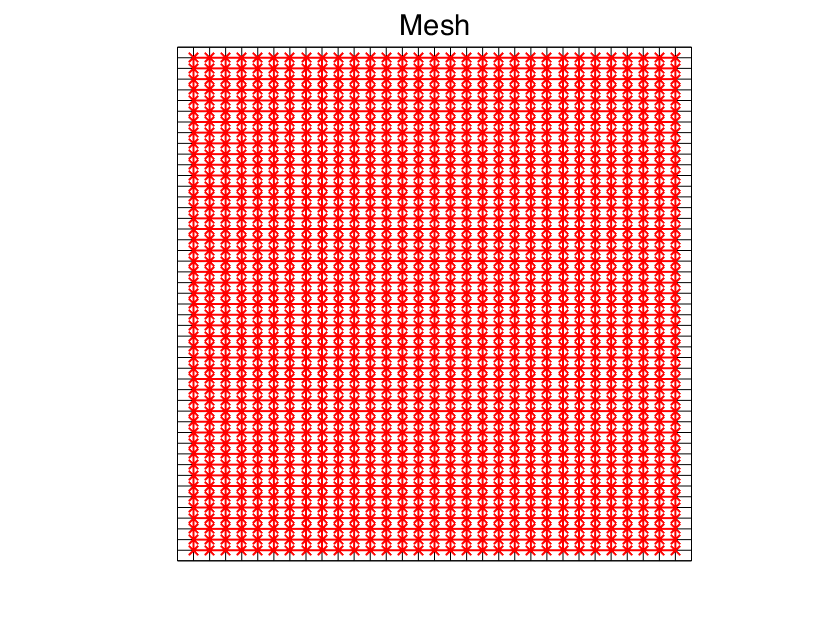

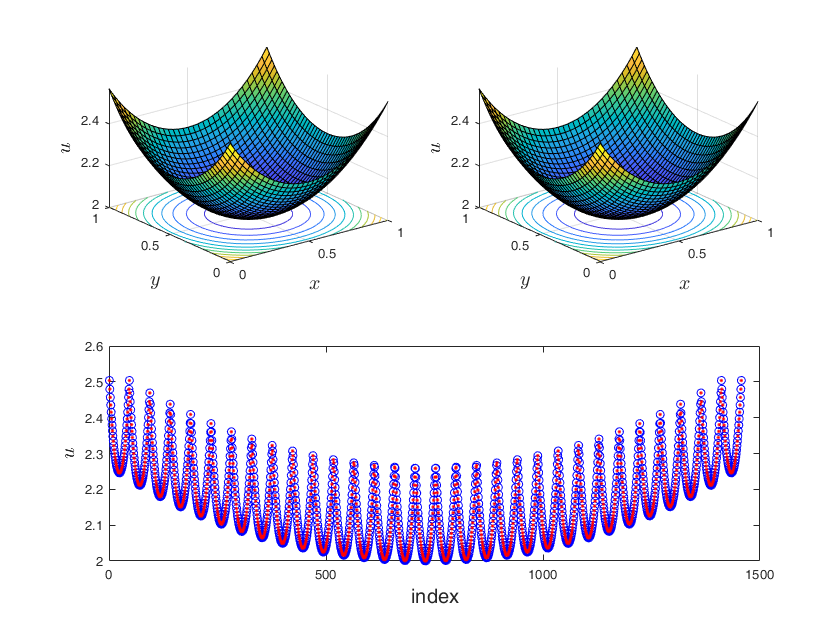

tic
Au1 = @(x, y)(exp((1/2 - x).^2) + exp((1/2 - y).^2));
f1 = @(x, y)(- 2*exp((x - 1/2)^2) - 2*exp((y - 1/2)^2) - exp((x - 1/2)^2)*(2*x - 1)^2 - exp((y - 1/2)^2)*(2*y - 1)^2);
u11 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au1, f1, 1 );

Error_Max_norm: 6.72566e-05
Error_L2_norm: 3.37302e-05

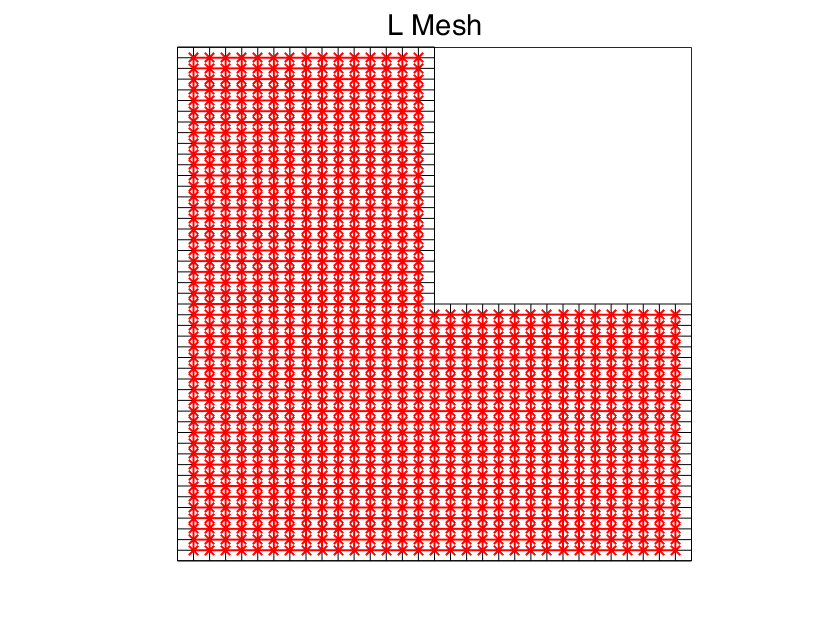

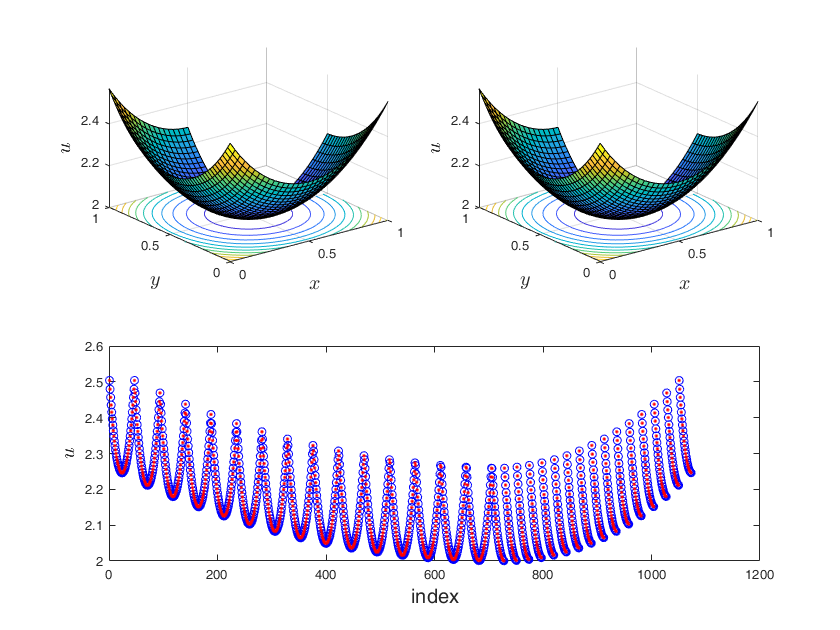

u12 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au1, f1, 2 );

toc

时间已过 3.207866 秒。



$$u(x+y) = \sin(x+y)$$


Error_Max_norm: 7.10905e-06
Error_L2_norm: 3.904e-06

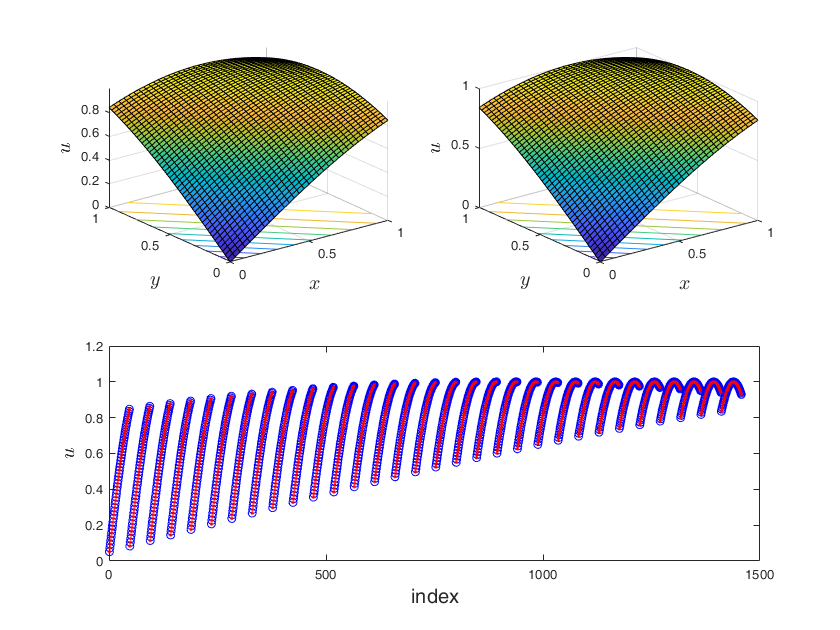

tic
Au2 = @(x, y)(sin(x+y));
f2 = @(x, y)(2*sin(x + y));
u21 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au2, f2, 1 );

Error_Max_norm: 2.7746e-06
Error_L2_norm: 1.44616e-06

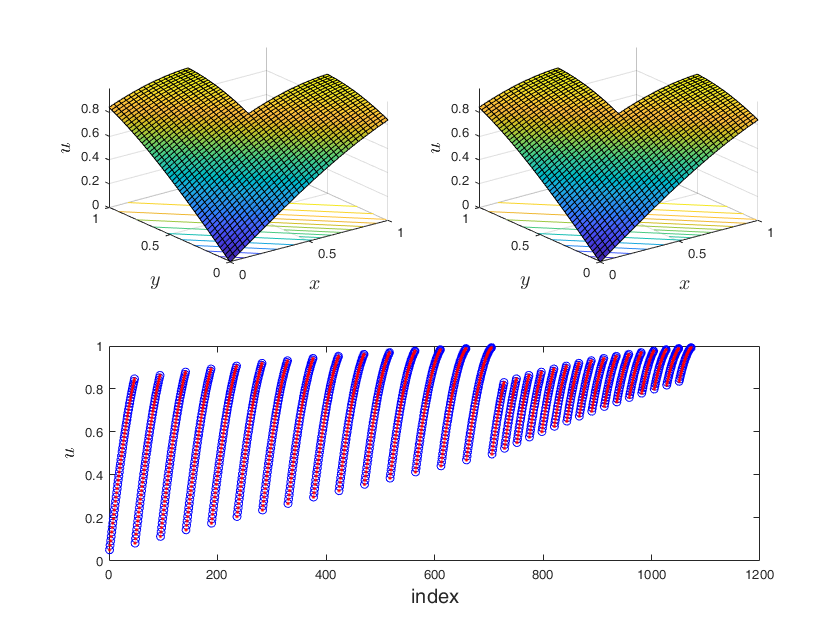

u22 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au2, f2, 2 );

toc

时间已过 2.306443 秒。



$$u\left( x,y \right) =\sin \left( x\left( x-1 \right) \right) \sin \left( y\left( y-1 \right) \right) $$


Error_Max_norm: 1.40822e-06
Error_L2_norm: 5.6068e-07

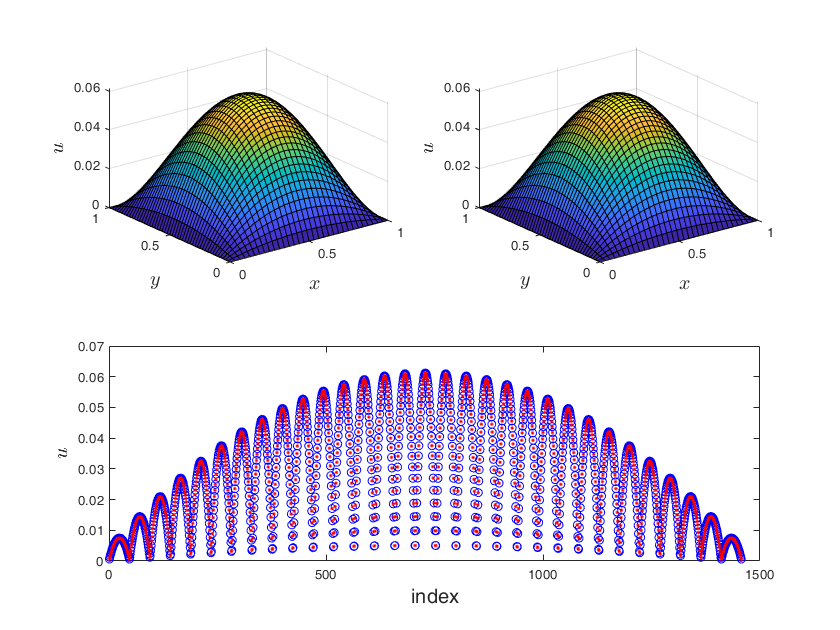

tic
Au3 = @(x, y)(sin(x.*(x-1)).*sin(y.*(y-1)));
f3 = @(x, y)(sin(x*(x - 1))*sin(y*(y - 1))*(2*x - 1)^2 - 2*cos(y*(y - 1))*sin(x*(x - 1)) - 2*cos(x*(x - 1))*sin(y*(y - 1)) + sin(x*(x - 1))*sin(y*(y - 1))*(2*y - 1)^2);

u31 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 1 );

Error_Max_norm: 9.71672e-07
Error_L2_norm: 4.03184e-07

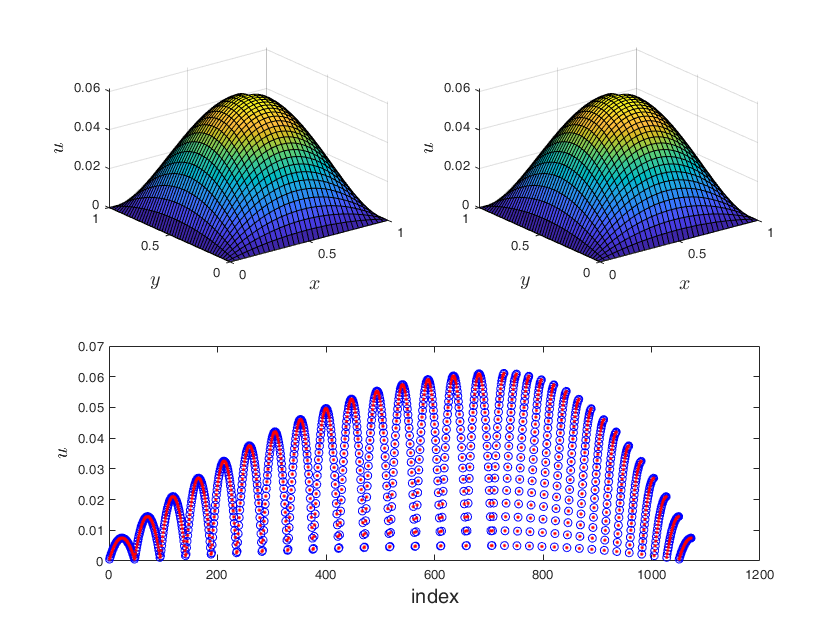

u32 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 2 );

toc

时间已过 2.107805 秒。
